Recreating the molecular-clutch model from fig. 1 of this paper: https://www.science.org/doi/10.1126/science.1163595

% Recreated this model using the code we got from the paper writers as a
% reference... still need to comment + clean this up more - Brandon

clear all

% Model Parameters (extracted from Table S1 in SI)
% ====================================================
%                  [Unit]   Variable definition
% ====================================================
n_m = 75;          %          Number of myosin motors
F_m = -2;          % [pN]     Single myosin motor stall force
v_u = -120;        % [nm/s]   Unloaded myosin motor velocity
n_c = 75;          %          Number of molecular clutches
k_on = 1;          % [s^(-1)] Rate of clutch binding
k_off = 0.1;       % [s^(-1)] Rate of clutch unbinding
F_b = -2;          % [pN]     Characteristic bond rupture force
k_clutch = 5;      % [pN/nm]  Molecular clutch spring constant

% Drug limitation
n_m_min = floor(0.03*n_m);  % Minimum amount of myosion motors that 
                            % can not be inhibit

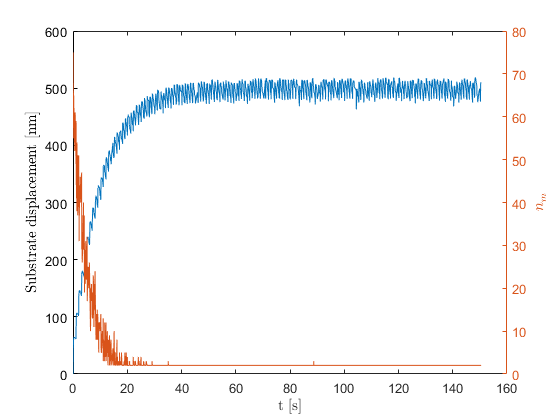

% Running Variables
% =======================
x_clutches = zeros(1, n_c);
clutch_states = zeros(1, n_c);
x_substrate = 0;
t = 0;
events_simulated = 2000;
x_substrates_t = zeros(1, events_simulated);
t_points = zeros(1, events_simulated);
k_substrate = 0.1;

% Drug considerations for model
n_m_active = [n_m];
n_m_states = ones(1,n_m); % Initialize number of binding sites for
                        %  ATP (1) and Drug (0) of myosin motors
C0 = 0;                 % Initial concentration of drug before treatment 
C = [C0];               % Concentration of drug across time
Dose = 50;              % [ng] Dose of drug per day
treatment_day = 0;      % Treatment time in integer days
treatment_time = 0;     % Total treatment time
t_c = [0];              % Time when the drug concentration in the cell
                        % is calculated
                        
for i = 1:events_simulated

    %Calculate concentration of drug, 
    if i>1
       [n_m_active(i), n_m_states, treatment_day, treatment_time, C(i), C0] = n_m_inhibition(n_m,n_m_states,n_m_min,Dose,treatment_day,treatment_time,dt,t,C0);
    end
            
    % Calculate velocity of the F-actin
    F_stall = n_m_active(i)*F_m;
    F_sub = k_substrate * x_substrate;
    if F_sub < F_stall
        v_filament = v_u * (1 - (F_sub / F_stall));
    else
        v_filament = 0;
    end

    % Calculate force on the clutches
    F_clutch = k_clutch * (x_clutches - x_substrate);
    
    % Use Gillepsie algorithm to simulate the next event
    [is_bind, state_idx, dt] = simulate_next_event(clutch_states, F_clutch, k_on, F_b, k_off);
    
    % Change the state of the clutch
    clutch_states(state_idx) = is_bind;
    if ~is_bind
        x_clutches(state_idx) = x_substrate;
    end
    
    engaged_clutch_idx = find(clutch_states==1);
    disengaged_clutch_idx = find(clutch_states==0);
    
    % Find the position of the substrate
    x_substrate = (k_clutch * sum(x_clutches(engaged_clutch_idx))) / (k_substrate + (length(engaged_clutch_idx) * k_clutch));
    
    % Displace engaged clutches
    x_clutches(engaged_clutch_idx) = x_clutches(engaged_clutch_idx) + (v_filament * dt);
    
    % Set disengaged clutch displacement to the displacement of the
    % substrate
    x_clutches(disengaged_clutch_idx) = x_substrate;
    t = t + dt;
    t_c(i) = t;
    x_substrates_t(i) = x_substrate;
    t_points(i) = t;
end
figure(1)
plot(t_c,C)
hold on
xlabel("$t [s]$","Interpreter","latex");
ylabel("Substrate displacement [nm]","Interpreter","latex")
yyaxis right
plot(t_c,n_m_active)
hold on
xlabel("t [s]","Interpreter","latex");
ylabel("$n_{m}$","Interpreter","latex");

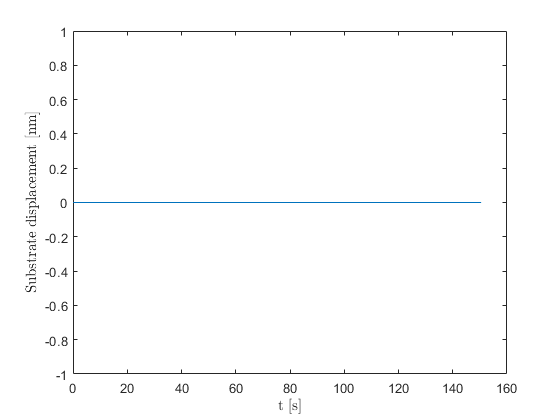

figure(2)
plot(t_points, x_substrates_t, '-');
xlabel("t [s]","Interpreter","latex");
ylabel("Substrate displacement [nm]","Interpreter","latex")

% Running Variables
% =======================
x_clutches = zeros(1, n_c);
clutch_states = zeros(1, n_c);
x_substrate = 0;
t = 0;
events_simulated = 1e5;
v_filaments_t = zeros(1, events_simulated);
dts = zeros(1, events_simulated);
k_substrates = logspace(-1, 2, 10); % [pN/nm]  Substrate spring constant
average_vs = zeros(1, length(k_substrates));
tic
i = 1;

for k_substrate = k_substrates
    
    % Drug considerations for model
    n_m_active = [n_m];
    n_m_states = ones(1,n_m); % Initialize number of binding sites for
                              %  ATP (1) and Drug (0) of myosin motors
    C0 = 0;                   % Initial concentration of drug before treatment 
    C = [C0];                 % Concentration of drug across time
    Dose = 50;                % [ng] Dose of drug per day
    treatment_day = 0;        % Treatment time in integer days
    treatment_time = 0;       % Total treatment time
    
    for ii = 1:events_simulated
        
        %Calculate concentration of drug, 
        if ii>1
           [n_m_active(ii), n_m_states, treatment_day, treatment_time, C(ii), C0] = n_m_inhibition(n_m,n_m_states,n_m_min,Dose,treatment_day,treatment_time,dt,t,C0);
        end
                
        % Calculate velocity of the F-actin
        F_stall = n_m_active(ii)*F_m;
        F_sub = k_substrate * x_substrate;
        if F_sub < F_stall
            v_filament = v_u * (1 - (F_sub / F_stall));
        else
            v_filament = 0;
        end
        % Calculate force on the clutches
        F_clutch = k_clutch * (x_clutches - x_substrate);
        
        % Use Gillepsie algorithm to simulate the next event
        [is_bind, state_idx, dt] = simulate_next_event(clutch_states, F_clutch, k_on, F_b, k_off);
        
        % Change the state of the clutch
        clutch_states(state_idx) = is_bind;
        if ~is_bind
            x_clutches(state_idx) = x_substrate;
        end
        
        engaged_clutch_idx = find(clutch_states==1);
        disengaged_clutch_idx = find(clutch_states==0);
        
        % Find the position of the substrate
        x_substrate = (k_clutch * sum(x_clutches(engaged_clutch_idx))) / (k_substrates(i) + (length(engaged_clutch_idx) * k_clutch));
        
        % Displace engaged clutches
        x_clutches(engaged_clutch_idx) = x_clutches(engaged_clutch_idx) + (v_filament * dt);
        
        % Set disengaged clutch displacement to the displacement of the
        % substrate
        x_clutches(disengaged_clutch_idx) = x_substrate;
        t = t + dt;

        % if x_substrate == 0
        %     clutch_states = zeros(1, n_c);
        % end
    
        v_filaments_t(ii) = v_filament;
        dts(ii) = dt;
    end
    
    average_vs(i) = sum(v_filaments_t .* dts) / sum(dts);
    i = i + 1;
end
toc

Elapsed time is 32.216536 seconds.


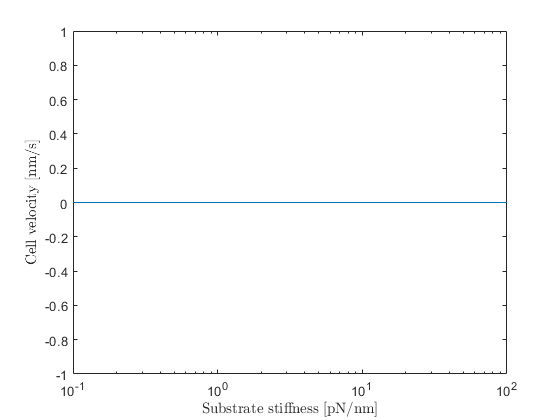

figure(3)
semilogx(k_substrates, -average_vs, '-');
xlabel("Substrate stiffness [pN/nm]","Interpreter","latex");
ylabel("Cell velocity [nm/s]","Interpreter","latex");

function [is_bind, state_idx, dt] = simulate_next_event(clutch_states, F_clutch, k_on, F_b, k_off)
    % Gillepsie algorithm implementation
    unengaged_clutch_indices = find(clutch_states==0);
    engaged_clutch_indices = find(clutch_states==1);

    if isempty(unengaged_clutch_indices)
        t_bind=inf;
    else
        t_bind=-log(rand(1, length(unengaged_clutch_indices)))/k_on;
    end

    if isempty(engaged_clutch_indices)
        t_unbind=inf;
    else
        t_unbind=-log(rand(1, length(engaged_clutch_indices)))./(k_off * exp(F_clutch(engaged_clutch_indices) / F_b));
    end

    [min_t_unbind, unbind_idx] = min(t_unbind);
    [min_t_bind, bind_idx] = min(t_bind);
    
    if min_t_bind < min_t_unbind
        % Binding event happens first
        is_bind = 1;
        state_idx = unengaged_clutch_indices(bind_idx);
        dt = min_t_bind;
    else
        % Unbinding event happens first
        is_bind = 0;
        state_idx = engaged_clutch_indices(unbind_idx);
        dt = min_t_unbind;
    end
end